# Example: MHKiT-MATLAB Loads Example 

The following example will help familiarize you with some of the functions in the mhkit loads module that you can use to assist you in your loads analysis. 

In this example, since there is no known field loads data for MHK devices, this data comes from a land based wind turbine. We have a database of 331 files, each containing 10 minutes of data sampled at 50Hz. 

As a start, lets look at the data for one of these files to figure out what formatting we need to apply. 

data=readtable('../examples/data/data_loads_example.csv');
disp(data)

    Timestamp     Time     uWind_80m    WD_ModActive    WD_Nacelle    WD_NacelleMod    LSSDW_Tq     LSSDW_My     LSSDW_Mz        TTTq       TT_ForeAft    TT_SideSide    TB_ForeAft    TB_SideSide    BL3_FlapMom    BL3_EdgeMom    BL1_FlapMom    BL1_EdgeMom    ActivePower     yawoffset 
    _________    ______    _________    ____________    __________    _____________    _________    ________    __________    __________    __________    ___________    <s

 Our file above shows us that we have two references to time, but neither are in the right format. The "Timestamp" column is what will give us the datetime index that we are looking for, but we first need to convert it from microsoft excel format to unix time.

newtime = excel_to_datetime(data.Timestamp);
data.time = newtime.' 

data = 30000×21 table
    Timestamp    Time    uWind_80m    WD_ModActive    WD_Nacelle    WD_NacelleMod    LSSDW_Tq    LSSDW_My    LSSDW_Mz     TTTq      TT_ForeAft    TT_SideSide    TB_ForeAft    TB_SideSide    BL3_FlapMom    BL3_EdgeMom    BL1_FlapMom    BL1_EdgeMom    ActivePower    yawoffset            time        
    _________    ____    _________    ____________    __________    _____________    ________    ________    ________    _______    __________</

## Damage Equivalent Loads

Lets say that we wanted to investigate fatigue. We can do this by calculating short-term damage equivalent loads (DELs). To use this function, we need the variable we want to analyze and its corresonding material slope factor. In this instance, we want to just look at our tower base moment and our blade 1 root flap moment. Our tower is steel while our blade is composite so they will have different material slopes. 

We call our function and apply the default inputs of using at least 100 bins for the load ranges and we let t=600 seconds so that we get an equivalent 1Hz DEL for our 10 minute file. 

% use the fatigue function to calculate the damage equivalent load for this file
DEL_tower = damage_equivalent_load(data.TB_ForeAft,4,'bin_num',100,'data_length',600)

DEL_tower = 3.9144e+03

DEL_blade = damage_equivalent_load(data.BL1_FlapMom,10,'bin_num',100,'data_length',600)

DEL_blade = 1.4359e+03

## Calculate Loads Statistics 

Another important part of loads analysis is looking at statistics. Here, we use another function to help us calculate the mean, max, min, and std for this 10 minute file. Per standards, a valid statistical window has to be consecutive in time with the correct number of datapoints. So if this 10 minute file did not meet this criteria, then no stats would be generated and a warning message would appear. 

NOTE: Sometimes individual files may contain enough data for multiple statistical windows. This function can still handle this scenario as long as the correct inputs are specified.

% First we need to convert the Matlab table to a structure
data = removevars(data,{'Timestamp','Time'});
datast = table2struct(data,'ToScalar',true)

datast = struct with fields:
        uWind_80m: [30000×1 double]
     WD_ModActive: [30000×1 double]
       WD_Nacelle: [30000×1 double]
    WD_NacelleMod: [30000×1 double]
         LSSDW_Tq: [30000×1 double]
         LSSDW_My: [30000×1 double]
         LSSDW_Mz: [30000×1 double]
             TTTq: [30000×1 double]
       TT_ForeAft: [30000×1 double]
      TT_SideSide: [30000×1 double]
       TB_ForeAft: [30000×1 double]
      TB_SideSide: [30000×1 double]
      BL3_FlapMom: [30000×1 double]
      BL3_EdgeMom: [30000×1 double]
      BL1_FlapMom: [30000×1 double]
      BL1_EdgeMom: [30000×1 double]
      ActivePower: [30000×1 double]
        yawoffset: [30000×1 double]
             time: [30000×1 datetime]


% calculate the means, maxs, mins, and stdevs of this file
stats = get_statistics(datast,50);
% show the mean results 
disp(stats.mean)

        uWind_80m: 7.7733
     WD_ModActive: 1
       WD_Nacelle: 178.6123
    WD_NacelleMod: 178.6026
         LSSDW_Tq: 127.2442
         LSSDW_My: -252.2381
         LSSDW_Mz: 3.5032
             TTTq: 7.0326
       TT_ForeAft: -846.6634
      TT_SideSide: 271.4466
       TB_ForeAft: 3.7850e+03
      TB_SideSide: 7.1992
      BL3_FlapMom: -494.8583
      BL3_EdgeMom: 266.7904
      BL1_FlapMom: -452.6527
      BL1_EdgeMom: 21.2600
      ActivePower: 234.5783
        yawoffset: 0.0097



At this point, it would be nice to start visualizing some of this data. In order to do this, we need to calculate the stats and DELs for all the files in our database. In this case, it would be done through a loop that imports each file and applies all the functions we just saw.  To speed things up, this was already done so we just need to import the results.

% load statistics results from csv
dmeans = table2struct(readtable('../examples/data/data_loads_dfmeans.csv'),'ToScalar',true);
dmaxs = table2struct(readtable('../examples/data/data_loads_dfmaxs.csv'),'ToScalar',true);
dmins = table2struct(readtable('../examples/data/data_loads_dfmins.csv'),'ToScalar',true);
dstd = table2struct(readtable('../examples/data/data_loads_dfstd.csv'),'ToScalar',true);

Now that we have all of our stats, lets make a scatter plot that can give us a visual. Using the statplotter function, we can quickly create a standard scatter plot showing how load variables trend with wind speed.  Using this we can quickly spot expected trends and track down outliers.

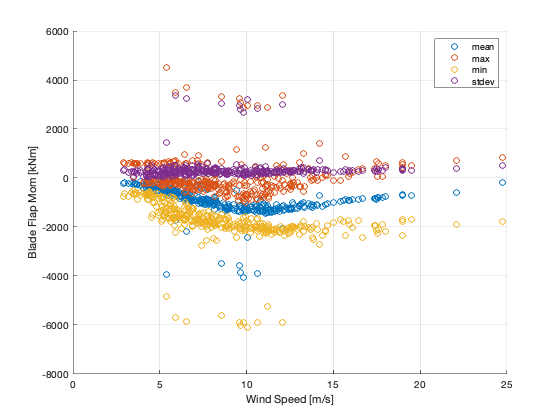

figure = plot_statistics(dmeans.uWind_80m,dmeans.BL1_FlapMom,dmins.BL1_FlapMom,dmaxs.BL1_FlapMom,"y_stdev",dstd.BL1_FlapMom,"xlabel",'Wind Speed [m/s]',"ylabel",'Blade Flap Mom [kNm]'); 

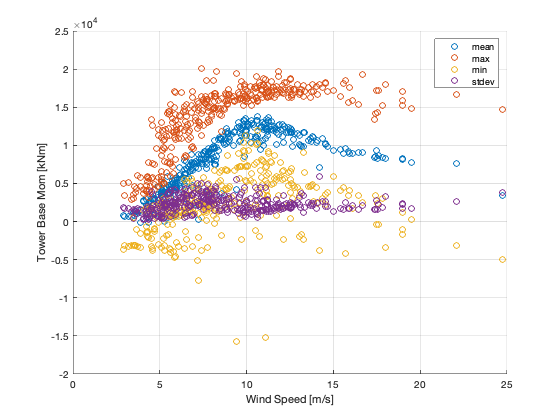

figure2 = plot_statistics(dmeans.uWind_80m,dmeans.TB_ForeAft,dmins.TB_ForeAft,dmaxs.TB_ForeAft,"y_stdev",dstd.TB_ForeAft,"xlabel",'Wind Speed [m/s]',"ylabel",'Tower Base Mom [kNm]'); 

Another common step is to bin the statistical data. This can easily be done with the bin_stats function from the loads module shown below. A warning message will show if there are any bins that were not filled.

% create array containg wind speeds to use as bin edges
b_edges = 3:1:25 ;
% apply function for means, maxs, mins, and DELs 
wind_means = bin_statistics(dmeans,dmeans.uWind_80m,b_edges);

wind_max = bin_statistics(dmaxs,dmeans.uWind_80m,b_edges);

wind_min = bin_statistics(dmins,dmeans.uWind_80m,b_edges);

wind_DEL = bin_statistics(dmaxs,dmeans.uWind_80m,b_edges);


wind_min.averages

ans = struct with fields:
        uWind_80m: [2.1242 2.6876 2.7056 3.3882 3.5183 4.4126 4.9702 5.2069 5.9900 6.4778 6.9174 7.4898 8.6332 8.7020 9.7576 10.7850 11.9810 NaN NaN 13.4225 NaN 12.8033]
     WD_ModActive: [1 1 0.9804 0.9706 1 0.9667 0.8800 0.8929 0.8000 0.8889 0.8333 0.4286 0.8333 1 1 1 1 NaN NaN 1 NaN 1]
       WD_Nacelle: [127.0607 130.7174 122.3374 133.2028 126.1269 138.5453 135.3727 137.9705 139.5523 143.8574 141.2035 143.9961 148.8661 144.3943 140.9045 143.0126 155.3234 NaN NaN 148.8235 NaN 155.1982]
    WD_NacelleMod: [127.4743 130.7070 122.4330 132.8670 126.0917 138.4898 135.2934 137.7625 139.4351 143.8420 142.2155 144.0176 148.8703 144.4205 140.9982 142.9965 155.3069 NaN NaN 148.7675 NaN 155.2159]
         LSSDW_Tq: [-39.6790 -6.7869 41.1941 42.5489 63.1331 131.0433 226.0972 226.8785 302.8315 389.8238 408.7412 756.6704 669.4895 582.2949 623.1634 520.5891 639.6092 NaN NaN 480.6764 NaN -319.0469]
         LSSDW_My: [-340.6785 -354.2910 -377.8430 -425.5655 -471.7537 -474

Now lets make some more plots with the binned data. Here we use the binned data and corresponding standard deviations as inputs to the binplotter function.

bcenters = 3.5:1:24.5 

bcenters =     3.5000    4.5000    5.5000    6.5000    7.5000    8.5000    9.5000   10.5000   11.5000   12.5000   13.5000   14.5000   15.5000   16.5000   17.5000   18.5000   19.5000   20.5000   21.5000   22.5000   23.5000   24.5000


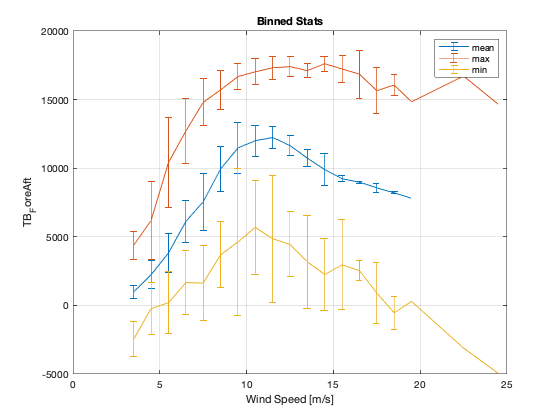

plot_bin_statistics(bcenters,wind_means.averages.TB_ForeAft,wind_max.averages.TB_ForeAft,wind_min.averages.TB_ForeAft,wind_means.std.TB_ForeAft,wind_max.std.TB_ForeAft,wind_min.std.TB_ForeAft,"xlabel",'Wind Speed [m/s]',"ylabel",'TB_ForeAft',"title",'Binned Stats');